Retrieve incident of close (A50_D10) and far (A50_Dfar) interaction with the Social target

if exist('ensb_Behav40')

counts=[];
counts=Behav_A50_D10;
counts(1:25,1)=0;
counts((length(counts)-15:length(counts)))=0;

Behav_A50_D10=counts;

for i=1:(length(Behav_A50_D10)-1)
    if counts(i)>0&&counts(i+1)>0
        counts(i+1)=counts(i)+counts(i+1);
    else
    end
end

CloseEvents=[];
CloseEvents=find(counts==5);
CloseEventsFrames(length(Behav_A50_D10))=0;
for i=1:numel(CloseEvents)
    CloseEventsFrames((CloseEvents(i)-10):CloseEvents(i))=1;
end

CloseC=CloseEvents;

counts=[];
counts=Behav_A50_Dfar;
counts(1:25,1)=0;
counts((length(counts)-15:length(counts)))=0;

Behav_A50_Dfar=counts;

for i=1:(length(Behav_A50_Dfar)-1)
    if counts(i)>0&&counts(i+1)>0
        counts(i+1)=counts(i)+counts(i+1);
    else
    end
end

CloseEvents=[];
CloseEvents=find(counts==5);
CloseEventsFrames(length(Behav_A50_Dfar))=0;
for i=1:numel(CloseEvents)
    CloseEventsFrames((CloseEvents(i)-10):CloseEvents(i))=1;
end

CloseF=CloseEvents;



Compute mean CaImg data during different interaction events

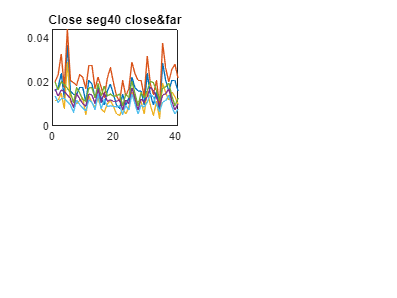

% ensb40 during close (CloseC) & far (CloseF) interaction events

NumCloseC=numel(CloseC);
NumCloseF=numel(CloseF);

% NeuP_CC refers to Close ensembles (first C) activity during close
% encounter (second C). NeuP_CF refers to Close ensembles during far
% encoutner (F)

mNeuP_C40C(NumCloseC,41)=0;
mNeuP_C40F(NumCloseF,41)=0;
sumNeuP_C40C(NumCloseC)=0;
sumNeuP_C40F(NumCloseF)=0;

mNeuP_C10C(NumCloseC,41)=0;
mNeuP_C10F(NumCloseF,41)=0;
sumNeuP_C10C(NumCloseC)=0;
sumNeuP_C10F(NumCloseF)=0;

% seg40 activities during close and far encounter

for i=1:NumCloseC
    mNeuP_C40C(i,:)=sum(NeuP(ensb_Behav40.ensbID,CloseC(i)-25:CloseC(i)+15))/numel(ensb_Behav40.ensbID);
    sumNeuP_C40C(i)=sum(mNeuP_C40C(i,:));
end

mmNeuP_C40C=mean(mNeuP_C40C);
sdNeuP_C40C=std(mNeuP_C40C);
semNeuP_C40C=sdNeuP_C40C/sqrt(NumCloseC-1);

for i=1:NumCloseF
    mNeuP_C40F(i,:)=sum(NeuP(ensb_Behav40.ensbID,CloseF(i)-25:CloseF(i)+15))/numel(ensb_Behav40.ensbID);
    sumNeuP_C40F(i)=sum(mNeuP_C40F(i,:));
end

mmNeuP_C40F=mean(mNeuP_C40F);
sdNeuP_C40F=std(mNeuP_C40F);
semNeuP_C40F=sdNeuP_C40F/sqrt(NumCloseF-1);

totalNeuP_C40C=sum(mmNeuP_C40C);
totalNeuP_C40F=sum(mmNeuP_C40F);

end


if isempty(extract(segment.session,'Def'))==0
    Figure1c_DistHead=mean(DistanceH)
    Figure1c_AngleHead=mean(Angle(isfinite(Angle)))
    Figure2a_D10=sum(numel(find(DistanceH<=10)))/numel(DistanceH)
    Figure2a_A50=sum(numel(find(Angle<=50)))/numel(Angle)
    if exist('ensb_Behav40')
        Figure3a_close=totalNeuP_C40C/8
        Figure3a_far=totalNeuP_C40F/8
        Figure3b_CSI=ensb_Behav40.ensbCSI_Behav_A50_D10
        Figure3c_EnsembleSize=ensb_Behav40.ensbPercent
        Figure4a_interaction=numel(ensb_Behav40.CloseEvents)
        tempMSIindex=isfinite(place.All_MSI);tempMSIfinite=find(tempMSIindex==1);finiteensbID=intersect(ensb_Behav40.ensbID,tempMSIfinite);
        Figure4c_mSI=mean(place.All_MSI(finiteensbID))
    end
    FigureS2a_Dfar=sum(numel(find(DistanceH>=25)))/numel(DistanceH)
    FigureS2b_Compass=mean(Compass(isfinite(Compass)))
    FigureS2c_Displacement=sum(Displacement)/length(Displacement)*5*60
    FigureS2d_ISR=sum(mean(NeuP))/numel(DistanceH)*5
   
else
    Figure1d_DistHead_SIT1=mean(DistanceH(startS1:endS1))
    if exist('endS2new')
        endS2=endS2new;
    end
    Figure1d_DistHead_SIT2=mean(DistanceH(startS2:endS2))
    Figure1d_AngleHead_SIT1=mean(Angle(startS1:endS1))
    Figure1d_AngleHead_SIT2=mean(Angle(startS2:endS2))
    if exist('ensb_Behav40')
        tempMSIindex=isfinite(place.All_MSI);tempMSIfinite=find(tempMSIindex==1);finiteensbID1=intersect(ensb_Behav40.ensbID,tempMSIfinite);
        Figure4a_interaction_SIT=numel(find(ensb_Behav40.CloseEvents<endS2))
        Figure4c_mSI_SIT=mean(place.All_MSI(finiteensbID1))
    end
        FigureS3a_ISR_SIT1=sum(mean(NeuP(:,startS1:endS1)))/numel(DistanceH)*5
        FigureS3a_ISR_SIT2=sum(mean(NeuP(:,startS2:endS2)))/numel(DistanceH)*5
end

Figure1c_DistHead = 24.3296

Figure1c_AngleHead = 78.3968

Figure2a_D10 = 0.1135

Figure2a_A50 = 0.3484

Figure3a_close = 0.0833

Figure3a_far = 0.0645

Figure3b_CSI = 0.1572

Figure3c_EnsembleSize = 0.1713

Figure4a_interaction = 17

Figure4c_mSI = 0.0526

FigureS2a_Dfar = 0.4634

FigureS2b_Compass = -15.8497

FigureS2c_Displacement = 265.6156

FigureS2d_ISR = 0.0400